Calcular los modos de DMD:

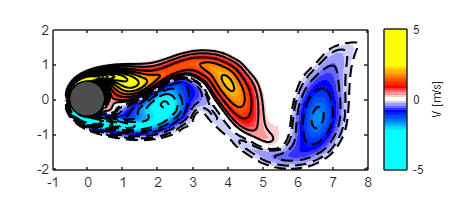

ans =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [500 300 600 260]
       Units: 'pixels'

  Show all properties


load("CYLINDER_ALL.mat", "VORTALL")
Avortex1 = VORTALL(:,1:end-1);
Avortex2 = VORTALL(:,2:end);
%Empiezo haciendo el SVD
%VORTALL ya está organizado.
[U, S, V] = svd(Avortex1, "econ");

dt = 10*0.02;
r = 10;
U = U(:, 1:r);
S = S(1:r,1:r);
V = V(:, 1:r);
Awierd = U'*Avortex2*V*inv(S);

[W,eigs] = eig(Awierd);
Phi = Avortex2*V*inv(S)*W;
lambda = diag(eigs);
omega = log(lambda)/dt;

%Calcular los modos
x0 = Avortex1(:, 1);
b = Phi\x0;

mm1 =120;  %size(Avortex1, 2);
tiempo = zeros(r, mm1);
t = (0:mm1 -1)*dt; 

for iter = 1:mm1 
    tiempo(:,iter) = (b.*exp(omega*t(iter)));
end

Xdmd = Phi*tiempo;

nx = 199;
ny = 449;
prueba1 = reshape(Xdmd(:,75),nx,ny);
plotVortex(real(prueba1))

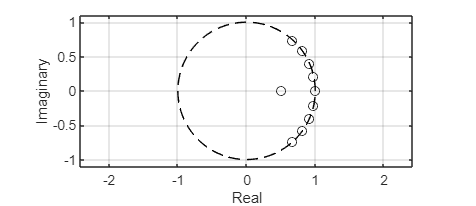


theta = (0:1:100)*2*pi/100;
plot(cos(theta),sin(theta),"k--") % plot unit circle
hold on, grid on
scatter(real(diag (eigs)),imag(diag(eigs)),"ok")
axis ([-1.1 1.1 -1.1 1.1]);
axis equal;
xlabel("Real")
ylabel("Imaginary")

s = size(U,2); %Total number of snapshots23
ti = 0;
dt = 0.2;
tf = (s-1)*dt;
t = ti:dt:tf;

function f1 = plotVortex(Vortex)
    
    load CCcool.mat
    f1 = figure;
    vortmin = -5;
    vortmax = 5;

    Vortex(Vortex>vortmax) = vortmax;
    Vortex(Vortex<vortmin) = vortmin;

    imagesc(Vortex);
    colormap(CC);

    xticks([1 50 100 150 200 250 300 350 400 449])
    xticklabels({'-1','0','1','2','3','4','5','6','7','8'})
    yticks([1 50 100 150 199])
    yticklabels({'2','1','0','-1','-2'})
    set(gcf,'Position',[500 300 600 260])
    axis equal
    hold on

    contour(Vortex , [vortmin-0.5:0.5:-0.5 -0.250 -0.125], "--k", "LineWidth",1.4)
    contour(Vortex , [0.250 0.5:0.5:vortmax], "-k", "LineWidth",1.4)
    cb = colorbar;
    ylabel(cb,'V [m/s]');

    theta = [0:0.1:359.9]';
    x = ones(size(theta,2));
    y = ones(size(theta,2));
    x = 49+25*sind(theta);  %Son esos centro porque la imagen está escalada
    y = 99+25*cosd(theta);
    fill(x,y,[.3 .3 .3])  % place cylinder
    plot(x,y,'k','LineWidth',1.2) % cylinder boundary
    hold off

end

